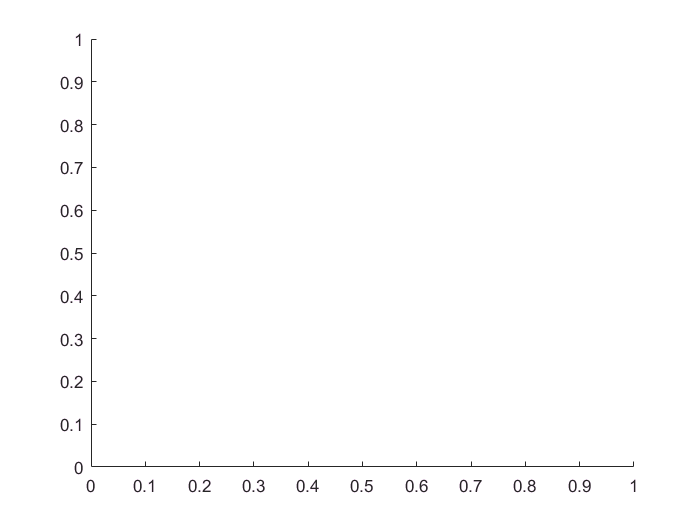

clear all
close all
L_test1 = [340 200 200 200 200 126 4];

q_test0 = [0 0 0 0 0 0 0];
q_test1 = [pi/2 0 0 0 0 0 0];
q_test2 = [0 pi/2 0  pi/2 0 pi/2 0];
q_test3 = [0 0.2 0.5  1 0.5 1 0];

figure;
hold on

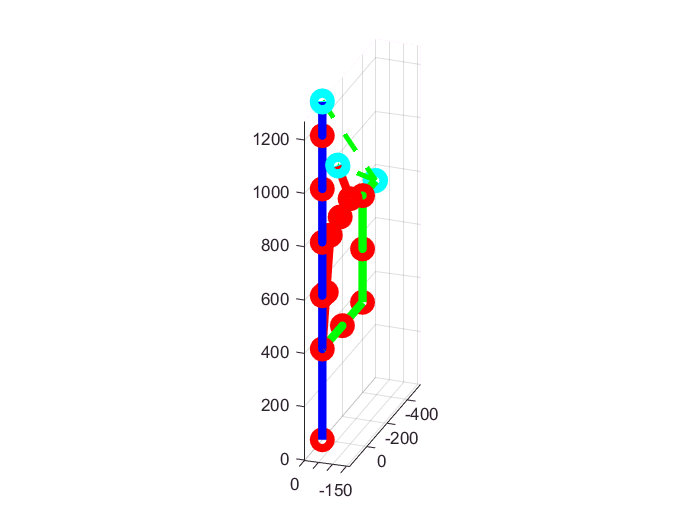

draw_trayectory_robot(q_test1,q_test2,q_test3,L_test1) %draw trayectory for 3 positions

syms q1_symb q2_symb q3_symb q4_symb q5_symb q6_symb q7_symb real
syms d1_symb d2_symb d3_symb d4_symb d5_symb d6_symb d7_symb real

q_symb=[q1_symb q2_symb q3_symb q4_symb q5_symb q6_symb q7_symb];
L_symb=[d1_symb d2_symb d3_symb d4_symb d5_symb d6_symb d7_symb];
%Jq=simplify(Jacobian(q_symb,L_symb))

%Jacobbian
Jq1=Jacobian(q_test1,L_test1)

Jq1 =          0  930.0000         0  530.0000         0  130.0000         0
         0   -0.0000         0   -0.0000         0   -0.0000         0
         0         0         0         0         0         0         0
         0    0.0000         0    0.0000         0    0.0000         0
         0    1.0000         0    1.0000         0    1.0000         0
    1.0000         0    1.0000         0    1.0000         0    1.0000


**Jacobian-based methods**  


q_test3 = [0 0 pi/8 0.5 0 -1 0];
q_test3'

ans =          0
         0
    0.3927
    0.5000
         0
   -1.0000
         0


p_target= FK(q_test3,L_test1) %target end effector point

p_target =    1.0e+03 *

    0.0009   -0.0000   -0.0004   -0.1230
    0.0004    0.0001    0.0009    0.2970
         0   -0.0010    0.0001    1.1002
         0         0         0    0.0010



%Input: target position and orientation we want, initial joint positions, lenghts of links, type of IK

%Just Pseudo Inverser 
q_ik_pseudoInverse = IK_Jacobbian(p_target, q_test0, L_test1, 1) %number 1 - parameter for Just Pseudo Inverser 

q_ik_pseudoInverse =    1.0e+04 *

   -0.0001
    0.0000
   -0.0002
    0.0002
   -0.0000
   -0.0001
   -3.0412


p_ik_pseudoInverse = FK(q_ik_pseudoInverse,L_test1)

p_ik_pseudoInverse =    -0.3749   -0.9153    0.1472  -91.4930
   -0.8741    0.4019    0.2728 -388.7483
   -0.3089   -0.0264   -0.9507  371.1673
         0         0         0    1.0000



%Weighted Pseudo Inverser 
q_ik_pseudoInverse_weighted = IK_Jacobbian(p_target, q_test0, L_test1, 2)%number 2 - parameter for Just Weighted Pseudo Inverser 

q_ik_pseudoInverse_weighted =     0.1752
   -0.0916
    0.3515
    0.8436
    0.1526
    1.2197
    0.3825


p_ik_pseudoInverse_weightedp_ik_pseudoInverse_weightedp_ik_pseu = FK(q_ik_pseudoInverse_weighted,L_test1)

p_ik_pseudoInverse_weightedp_ik_pseudoInverse_weightedp_ik_pseu =    1.0e+03 *

    0.0006   -0.0008    0.0003   -0.1230
    0.0008    0.0005   -0.0002    0.2970
   -0.0000    0.0003    0.0009    1.1002
         0         0         0    0.0010



%Damped Least Squares
q_ik_Damped_Least_Squares = IK_Jacobbian(p_target, q_test0, L_test1, 3) %number 3 - parameter 

q_ik_Damped_Least_Squares =     0.6334
   -0.3720
   -2.4038
    0.3625
    2.6038
   -1.5033
   17.6945


p_ik_Damped_Least_Squares = FK(q_ik_Damped_Least_Squares,L_test1)

p_ik_Damped_Least_Squares =    1.0e+03 *

    0.0004    0.0006   -0.0007   -0.1230
    0.0004    0.0006    0.0007    0.2970
    0.0008   -0.0006    0.0000    1.1002
         0         0         0    0.0010


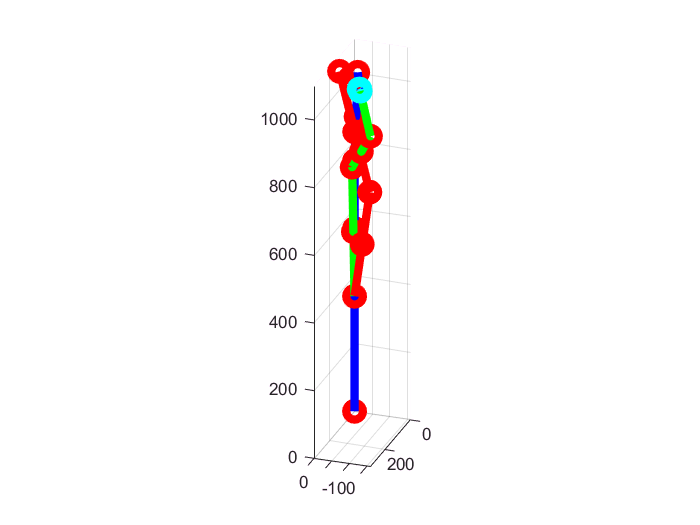



%draw target position, position using  weighted pseudo inverse and Damped Least Squares
draw_trayectory_robot(q_test3,q_ik_pseudoInverse_weighted,q_ik_Damped_Least_Squares,L_test1)

**Null-space methods**  

%Null Space 
q_test4 = [0 pi/6 pi/8 0.5 0 -1 0];
q_test4'

ans =          0
    0.5236
    0.3927
    0.5000
         0
   -1.0000
         0


p_target= FK(q_test4,L_test1) %target end effector point

p_target =    1.0e+03 *

    0.0009   -0.0000   -0.0004   -0.1230
    0.0003    0.0006    0.0008   -0.1229
    0.0002   -0.0008    0.0005    1.1469
         0         0         0    0.0010



q_ik_NullSpace = IK_NullSpace(p_target, q_test0, L_test1) %number 3 - parameter 

q_ik_NullSpace =    1.0e+07 *

    0.0000
    0.0000
    0.0000
   -0.0000
   -0.0000
    0.0000
    1.1343


q_ik_NullSpace2 = IK_NullSpace(p_target, q_test2, L_test1) %number 3 - parameter 

q_ik_NullSpace2 =    1.0e+03 *

   -0.0005
    0.0000
    0.0024
    0.0006
    0.0027
   -0.0014
    4.3278


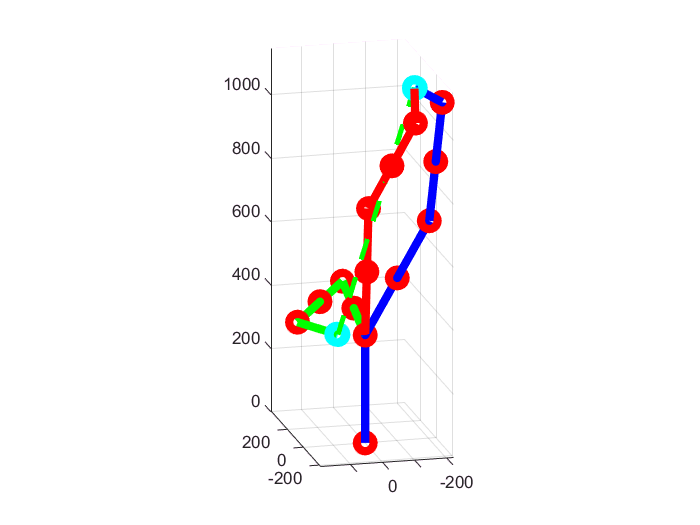

%draw target position, position using  weighted pseudo inverse and Damped Least Squares
draw_trayectory_robot(q_test4,q_ik_NullSpace,q_ik_NullSpace2,L_test1)

**Trayectory comparation**

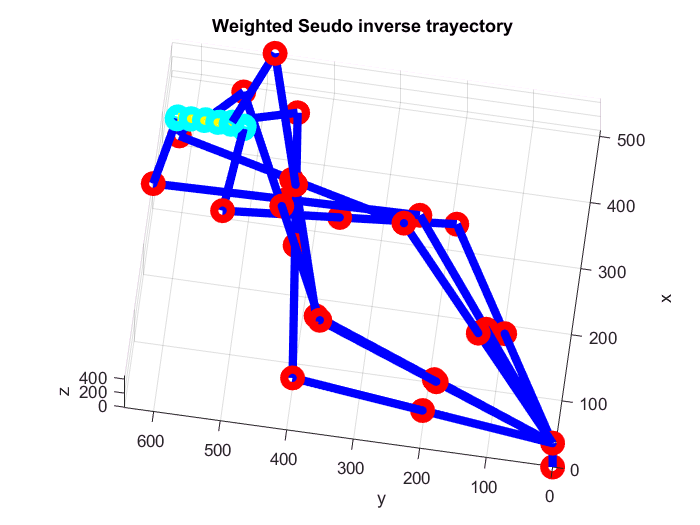

disty=500;
dline=20;
Y=[(disty+dline) (disty+2*dline) (disty+3*dline) (disty+4*dline) (disty+5*dline) (disty+6*dline)];
distx=400;
X=[distx distx distx distx distx distx];
distz=400;
Z=[distz distz distz distz distz distz];

%%Weighted Seudo inverse trayectory
figure;
hold on
xlim([0 365])
ylim([0 466])
zlim([-42 563])
view([-82 84])
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
title('Weighted Seudo inverse trayectory')
for i = 1:6
    p_target=Tx(X(i))*Ty(Y(i))*Tz(Z(i));
    q_i= IK_Jacobbian(p_target, q_test0, L_test1, 2);
    draw_robot(q_i,L_test1,'-b')
    
    if i>1
        T_new=FK(q_i,L_test1);
        plot3([T_last(1,4) T_new(1,4)],[T_last(2,4) T_new(2,4)],[T_last(3,4) T_new(3,4)],'--g','LineWidth', 3);
        plot3([X(i-1) X(i)],[Y(i-1) Y(i)],[Z(i-1) Z(i)],'--y','LineWidth', 5);
    end
    T_last=FK(q_i,L_test1);
end

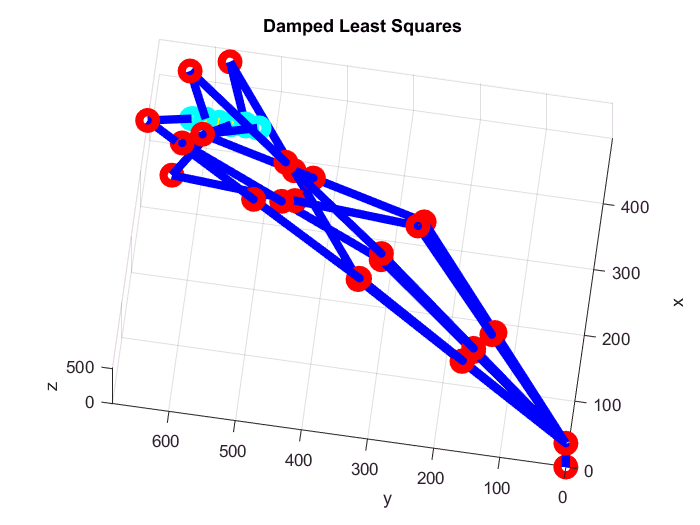


%%Damped Least Squares
figure;
hold on
xlim([0 365])
ylim([0 466])
zlim([-42 563])
view([-82 84])
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
title('Damped Least Squares')
for i = 1:6
    p_target=Tx(X(i))*Ty(Y(i))*Tz(Z(i));
    q_i= IK_Jacobbian(p_target, q_test0, L_test1, 3);
    draw_robot(q_i,L_test1,'-b')
    
    if i>1
        T_new=FK(q_i,L_test1);
        plot3([T_last(1,4) T_new(1,4)],[T_last(2,4) T_new(2,4)],[T_last(3,4) T_new(3,4)],'--g','LineWidth', 3);
        plot3([X(i-1) X(i)],[Y(i-1) Y(i)],[Z(i-1) Z(i)],'--y','LineWidth', 5);
    end
    T_last=FK(q_i,L_test1);
end

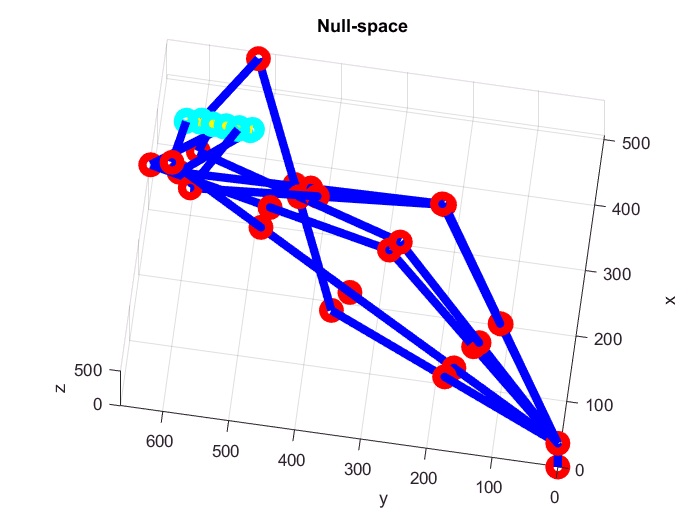


%%Null-space
figure;
hold on
xlim([0 365])
ylim([0 466])
zlim([-42 563])
view([-82 84])
grid on
axis equal
xlabel('x')
ylabel('y')
zlabel('z')
title('Null-space')
for i = 1:6
    p_target=Tx(X(i))*Ty(Y(i))*Tz(Z(i));
    q_i= IK_NullSpace(p_target, q_test2, L_test1);
    draw_robot(q_i,L_test1,'-b')
    
    if i>1
        T_new=FK(q_i,L_test1);
        plot3([T_last(1,4) T_new(1,4)],[T_last(2,4) T_new(2,4)],[T_last(3,4) T_new(3,4)],'--g','LineWidth', 3);
        plot3([X(i-1) X(i)],[Y(i-1) Y(i)],[Z(i-1) Z(i)],'--y','LineWidth', 5);
    end
    T_last=FK(q_i,L_test1);
end